syms clear

clear

syms z
N_1 = 1 - 3 * z^2 + 2 * z^3

$$N\_1 = 2\,z^{3}-3\,z^{2}+1$$

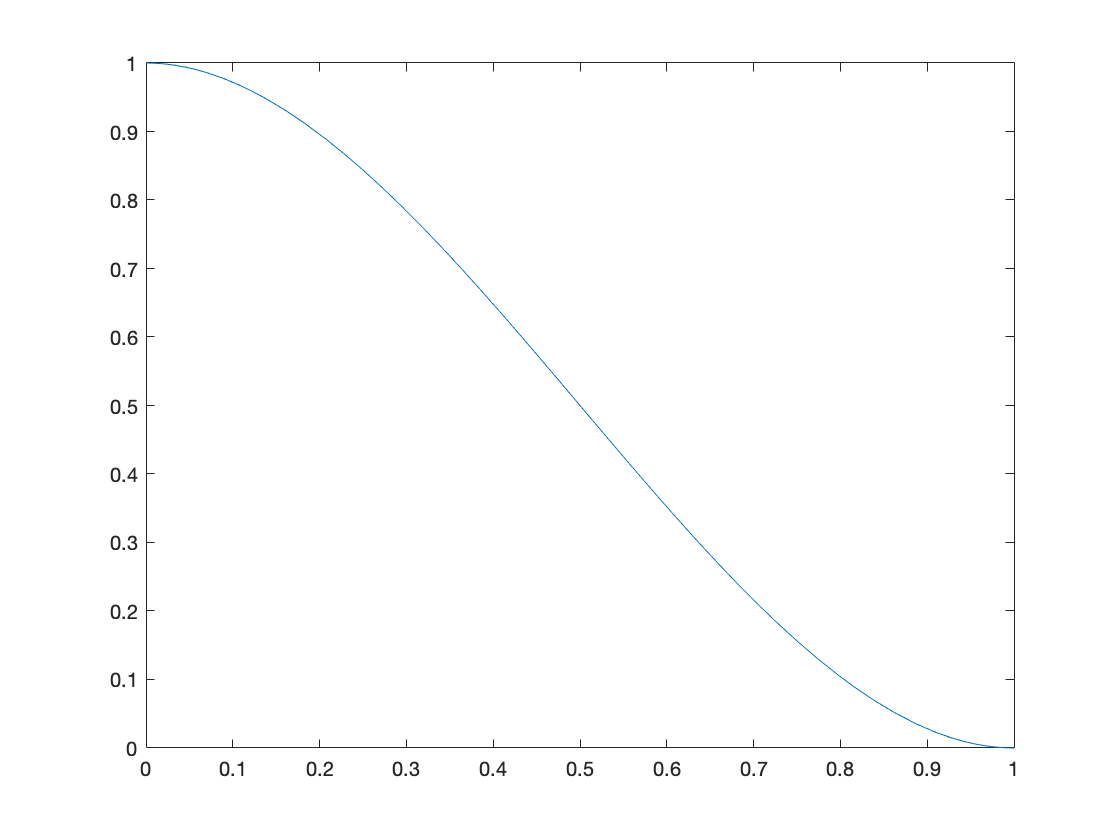

figure
fplot(N_1, [0, 1])


N_3 = 3 * z^2 - 2 * z^3

$$N\_3 = 3\,z^{2}-2\,z^{3}$$

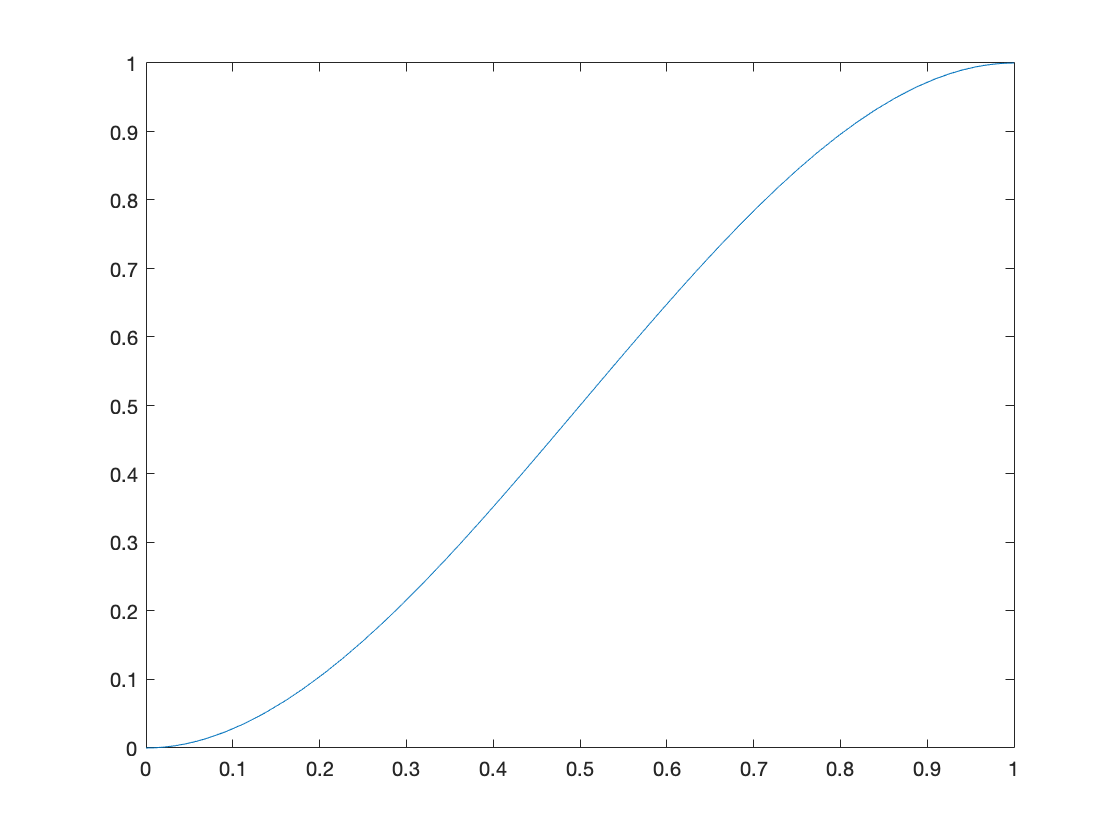

figure
fplot(N_3, [0, 1])


syms L
N_2 = L * z * (z - 1)^2

$$N\_2 = L\,z\,{\left(z-1\right)}^{2}$$

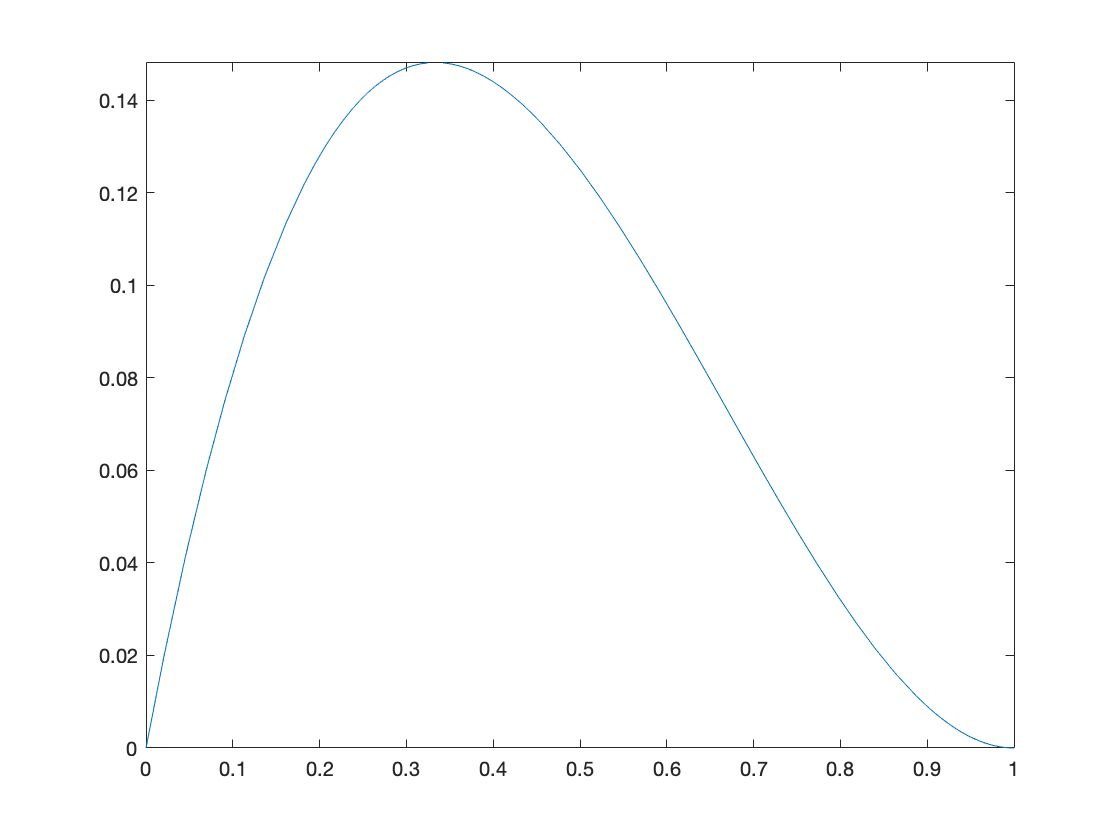

figure
% MuPAD code that caused issue 1: plot::Function2d(subs(N_2, L = 1), z = 0..1, L = -5..5)
aux1 = subs([0, 1], L, sym(5));
fplot(subs(subs(N_2, L, sym(1)), L, sym(5)), double(aux1))


N_4 = -(L * (z^2 - z^3))

$$N\_4 = -L\,\left(z^{2}-z^{3}\right)$$

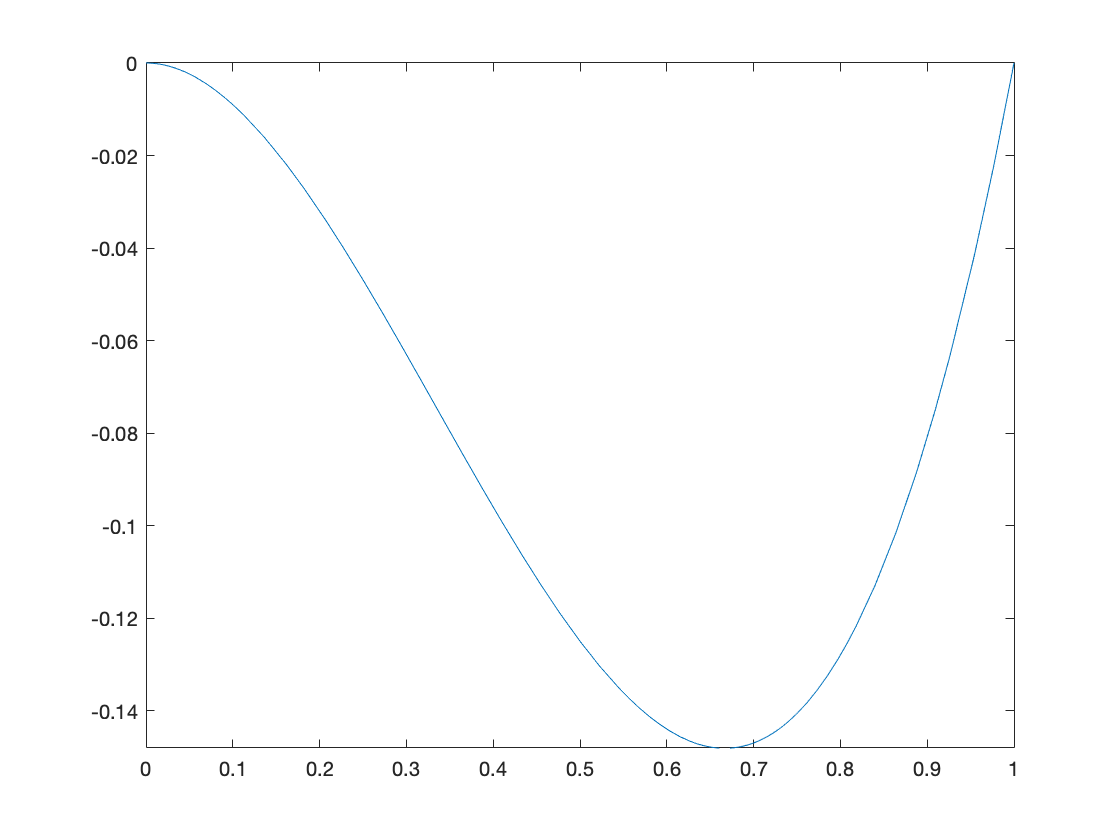

figure
% MuPAD code that caused issue 2: plot::Function2d(subs(N_4, L = 1), z = 0..1, L = -5..5)
aux2 = subs([0, 1], L, sym(5));
fplot(subs(subs(N_4, L, sym(1)), L, sym(5)), double(aux2))


syms X
N_1 = subs(N_1, z, X/L)

$$N\_1 = \frac{2\,X^{3}}{L^{3}}-\frac{3\,X^{2}}{L^{2}}+1$$

N_2 = subs(N_2, z, X/L)

$$N\_2 = X\,{\left(\frac{X}{L}-1\right)}^{2}$$

N_3 = subs(N_3, z, X/L)

$$N\_3 = \frac{3\,X^{2}}{L^{2}}-\frac{2\,X^{3}}{L^{3}}$$

N_4 = subs(N_4, z, X/L)

$$N\_4 = -L\,\left(\frac{X^{2}}{L^{2}}-\frac{X^{3}}{L^{3}}\right)$$


N = [N_1; N_2; N_3; N_4]

$$N = \left(\begin{array}{c} \frac{2\,X^{3}}{L^{3}}-\frac{3\,X^{2}}{L^{2}}+1\\ X\,{\left(\frac{X}{L}-1\right)}^{2}\\ \frac{3\,X^{2}}{L^{2}}-\frac{2\,X^{3}}{L^{3}}\\ -L\,\left(\frac{X^{2}}{L^{2}}-\frac{X^{3}}{L^{3}}\right) \end{array}\right)$$


B = symhold('transpose(diff(diff(N, X), X))')

$$B = {\left(\frac{\partial }{\partial X}\frac{\partial }{\partial X}N\right)}^{t}$$


B = transpose(diff(diff(N, X), X))

$$B = \left(\begin{array}{cccc} \frac{12\,X}{L^{3}}-\frac{6}{L^{2}} & \frac{2\,X}{L^{2}}+\frac{4\,\left(\frac{X}{L}-1\right)}{L} & \frac{6}{L^{2}}-\frac{12\,X}{L^{3}} & L\,\left(\frac{6\,X}{L^{3}}-\frac{2}{L^{2}}\right) \end{array}\right)$$


syms K
K == symhold('EI*int(transpose(B)*B, X, 0, L)')

$$ans = K=\mathrm{EI}\,\int B^{t}\,B\mathrm{d}X$$


syms EI
K = EI * int(transpose(B) * B, X, sym(0), L)

$$K = \begin{array}{l} \left(\begin{array}{cccc} \frac{12\,\mathrm{EI}}{L^{3}} & \sigma_{1} & -\frac{12\,\mathrm{EI}}{L^{3}} & \sigma_{1}\\ \sigma_{1} & \frac{4\,\mathrm{EI}}{L} & -\sigma_{1} & \frac{2\,\mathrm{EI}}{L}\\ -\frac{12\,\mathrm{EI}}{L^{3}} & -\sigma_{1} & \frac{12\,\mathrm{EI}}{L^{3}} & -\sigma_{1}\\ \sigma_{1} & \frac{2\,\mathrm{EI}}{L} & -\sigma_{1} & \frac{4\,\mathrm{EI}}{L} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{6\,\mathrm{EI}}{L^{2}} \end{array}$$

## Local Functions

## Helpers

function h = symhold(exprstring)
h = evalin(symengine, ['hold(' exprstring ' )']);
end